# PRÁCTICA No. 2

- `Práctica:` 2

- `Nombre: `Alison Betancourt

- `Fecha:` 29 de diciembre de 2023

## **GRÁFICOS**

**FUNCIONES BÁSICAS DE TRAZADO**

     `*Creación de un Trazado:`

La función de trazado tiene diferentes formas, según los parámetros que reciba (argumentos de entrada).

- y es un vector, `plot(y)` produce una gráfica lineal.

- `plot(x,y) `produce una gráfica de y versus x.

~ Utilice el operador de dos puntos para crear un vector de valores de x que van de 0 a 2π, calcule el seno de estosvalores y trazar el resultado:

x = 0:pi/100:2*pi;
y = sin(x);
plot(x,y)

Agregue etiquetas de eje y un título. Los caracteres `\pi` en la función `xlabel` crean el símbolo `π`. La propiedad `FontSize` en la función de título aumenta el tamaño del texto usado para el título.

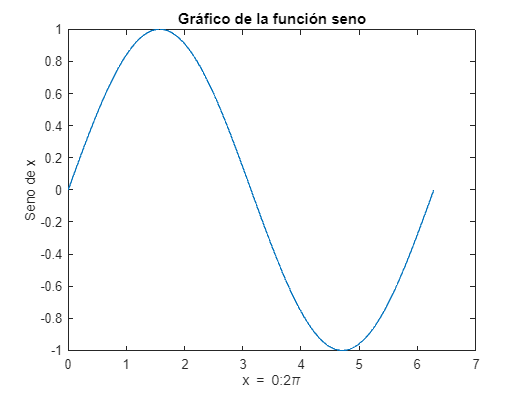

xlabel('x = 0:2\pi')
ylabel('Seno de x')
title('Gráfico de la función seno','FontSize',12)

     `*Trazar múltiples conjuntos de datos en un gráfico:`

Múltiples argumentos de pares x-y crean múltiples gráficos con una sola llamada para trazar.

x = 0:pi/100:2*pi;
y = sin(x);
y2 = sin(x-.25);
y3 = sin(x-.5);
plot(x,y,x,y2,x,y3)

La función de leyenda proporciona una manera fácil de identificar las líneas individuales.

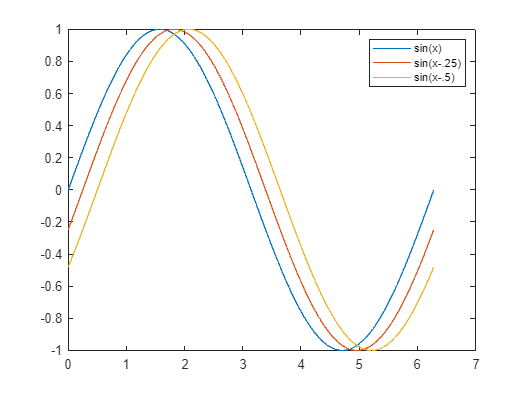

legend('sin(x)','sin(x-.25)','sin(x-.5)')

     `*Especificación de estilos y colores de línea:`

Se puede especificar color, estilos de líneas y marcadores, al usar el siguiente comando:

plot(x,y,'color_style_marker'): contiene de uno a cuatro caracteres construidos a partir de un color, un estilo de línea y un tipo de marcador.

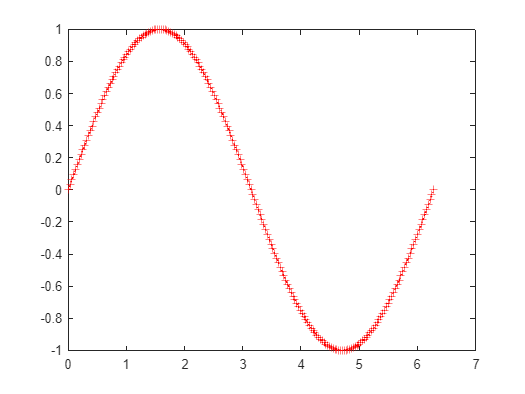

plot(x,y,'r:+')

- - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -

|Tipo                    |Valores          |Significados                                                       |

- - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -

|Color                  | 'c'                  | cian                                                                  |

|                           | 'm'                | magenta                                                           |

|                           | 'y'                 | amarillo                                                             |

|                           | 'r'                  | rojo                                                                   |

|                           | 'g'                 | verde                                                                |

|                           | 'b'                 | azul                                                                  |

|                           |  'w'               | blanco                                                               |

|                           |  'k'                | negro                                                                |

- - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -

|Estilo de             | '-'                 | sólido                                                                 |

|línea                   | '--'                | discontinuo                                                        |

|                           | ':'                 | punteado                                                           |

|                           | '-.'                | guión-punto                                                       |

|                           | sin caracter | sin línea                                                             |

- - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - 

|Tipo de               | '+'                | marca más                                                         |

|marcador            | 'o'                | círculo vacío                                                      |

|                           | '*'                 | asterisco                                                            |

|                           | 'x'                 | letra x                                                                 |

|                           | 's'                 | cuadrado vacío                                                  |

|                           | 'd'                 | diamante vacío                                                  |

|                           | '^'                 | triángulo ascendente vacío                                |

|                           | 'v'                 | triángulo descendente vacío                              |

|                           | '>'                 | triángulo que apunta hacia la derecha vacío     |

|                           | '<'                 | triángulo que apunta hacia la izquierda vacío    |

|                           | 'p'                 |  pentagrama vacío                                              |

|                           | 'h'                 |  hexagrama vacío                                               |

|                           | sin caracter  | sin marcador                                                       |

- - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - 

     `*Trazar líneas y marcadores:`

Si solo especifica un tipo de marcador pero no un estilo de línea, solo crea el gráfico usando el marcador pero no la línea.

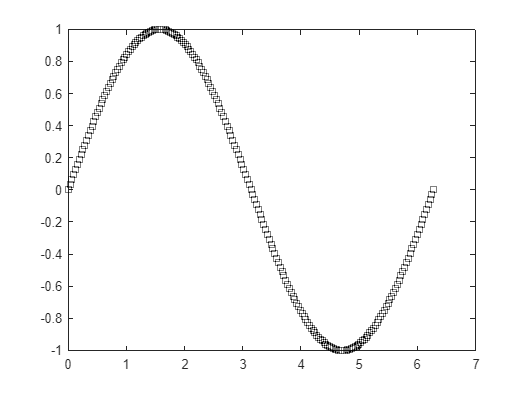

%va a marcar cuadrados negros pero no los va a unir
plot(x,y,'ks') 

%va a ytazar una línea de puntos rojos con marcadores de signo +
plot(x,y,'r:+')

COLOCAR MARCADORES EN CADA DÉCIMO PUNTO DE DATOS: Este ejemplo muestra cómo usar menos puntos de datos para trazar los marcadores que los que usa para trazar las líneas. Además, traza los datos dos veces usando un número diferente de puntos para la línea de puntos y el marcador.

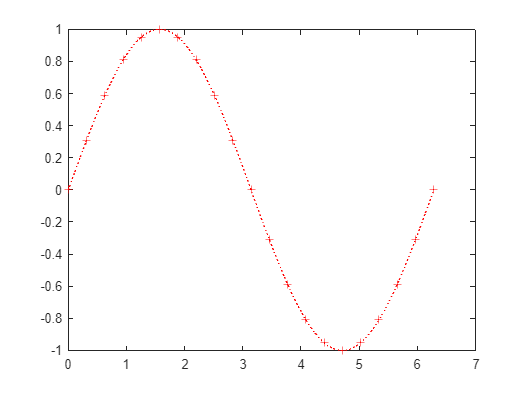

x1 = 0:pi/100:2*pi;
x2 = 0:pi/10:2*pi;
plot(x1,sin(x1),'r:',x2,sin(x2),'r+')

     `*Graficar datos imaginarios y complejos:`

Cuando pasa valores complejos como argumentos para trazar, MATLAB ignora la parte imaginaria, exceptocuando pasas un único argumento complejo. Para este caso especial, el comando es un atajo para ungráfica de la parte imaginaria versus la parte real.

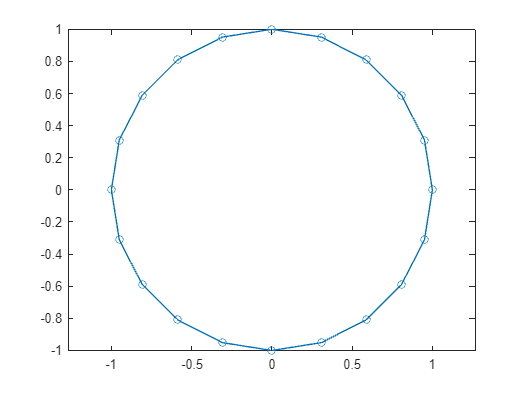

t = 0:pi/10:2*pi;
plot(exp(1i*t),'-o')
axis equal

El comando `axis equal` hace que los incrementos de las marcas individuales en los ejes x e y tengan la misma longitud, lo que hace que este gráfico tenga una apariencia más circular.

     `*Agregar gráficos a un gráfico existente:`

El comando `hold` le permite agregar gráficos a un gráfico existente. Cuando escribes: `hold on.`

MATLAB no reemplaza el gráfico, sino lo combina.

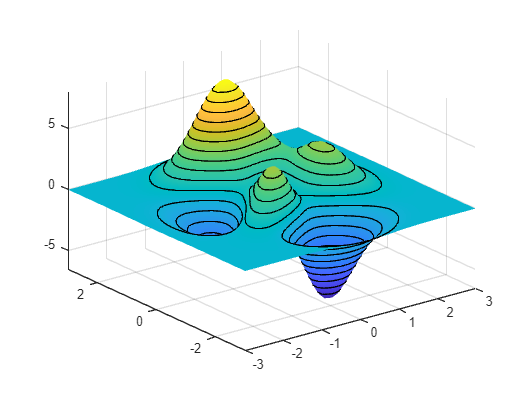

[x,y,z] = peaks;
% Crear parcela de superficie
surf(x,y,z)
% Elimina las líneas de los bordes y suaviza los colores.
shading interp
% Mantener el gráfico actual
hold on
% Agregue el gráfico de contorno al gráfico pcolor
contour3(x,y,z,20,'k')
% Volver al valor predeterminado
hold off

      *******`Figura ventanas:`

Las funciones de trazado abren automáticamente una nueva ventana de figura si ya no hay ventanas de figura creadas. Para convertir una ventana de figura existente en la figura actual, puede hacer clic con el mouse mientras el puntero está enesa ventana o puedes escribir, 

figure(n)

donde n es el número en la barra de título de la figura.

**LIMPIANDO LA FIGURA PARA UNA NUEVA PLOT**

Cuando ya existe una figura, la mayoría de los comandos de trazado borran los ejes y usan esta figura para crear la figura. Sin embargo, estos comandos no reestablecen las propiedades de la figura, como el color de fondo o del mapa de colores.

clf reset

     `*Mostrar múltiples gráficos en una figura:`

El comando `subplot` le permite mostrar múltiples trazados en la misma ventana o imprimirlos en el mismo trozo de papel. Por ejemplo, estas declaraciones trazan datos en tres subregiones de la ventana de la figura.

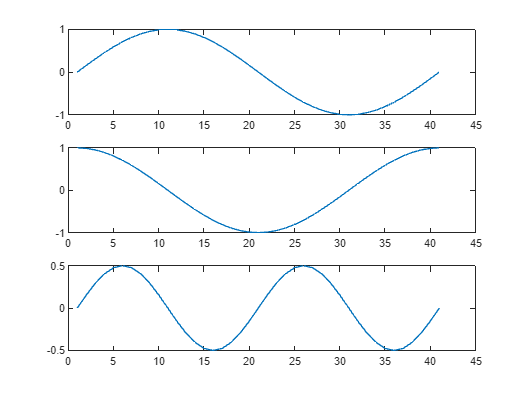

x = 0:pi/20:2*pi;
subplot(3,1,1); plot(sin(x))
subplot(3,1,2); plot(cos(x))
subplot(3,1,3); plot(sin(x).*cos(x))

     `*Controlando los ejes:`

El comando `axis`  proporciona una serie de opciones para configurar la escala, la orientación y la relación de aspecto.

**LÍMITES DE EJE AUTOMÁTICO Y MARCAS DE VERIFICACIÓN**

MATLAB selecciona los límites y los valores de las marcas de eje para producir un gráfico que muestra claramentelos datos. Sin embargo, puede establecer sus propios límites utilizando las funciones: `axis` or `xlim`, `ylim`, y `zlim`.

**ESTABLECER LÍMITES DE EJE**

El comando de eje le permite especificar sus propios límites:

`axis([xmin xmax ymin ymax])`

`axis([xmin xmax ymin ymax zmin zmax])`

axis auto %Para habilitar nuevamente los límites automáticos

**CONFIGURACIÓN DE AXIS ASPECT RATIO**

El comando de eje también le permite especificar una serie de modos predefinidos. Por ejemplo,

axis square %eje x y y tengan la misma longitud
axis equal %Los incrementos de las marcas individuales en los ejes tengan la misma longitud

Esto significa:

plot(exp(1i*(0:pi/10:2*pi)))

seguido del axis square o axis equal convierte el óvalo en un círculo propio:

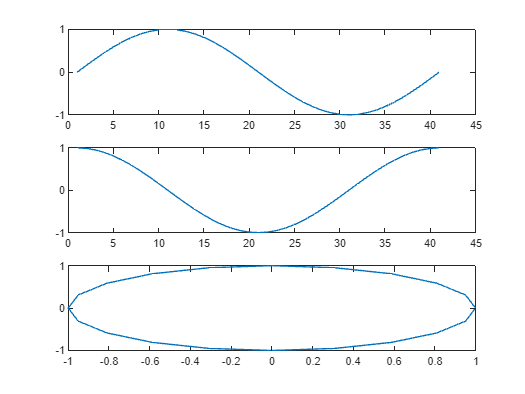

axis auto normal %Devuelve la escala del eje a su modo automático

**CONFIGURACIÓN DE LA VISIBILIDAD DEL EJE**

Puede utilizar el comando `axis` para hacer que el eje sea visible o invisible.

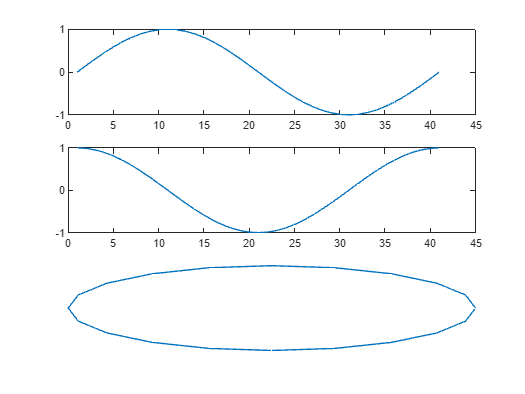

axis on %visible
axis off %invisible

**ESTABLECER LÍNEAS DE CUADRÍCULA**

El comando `grid` activa y desactiva las líneas de la cuadrícula. 

grid on %activa
grid off %desactiva

     `*Agregar etiquetas y títulos de ejes.`

Este ejemplo muestra cómo crear un gráfico y mejorar su presentación:

• 'Definir los límites de los ejes x e y (eje)

• Etiquete los ejes x e y (xlabel, ylabel)

• Agregar un título (título)

• Agregar una nota de texto en el gráfico (texto)

Produzca símbolos matemáticos mediante Latex.

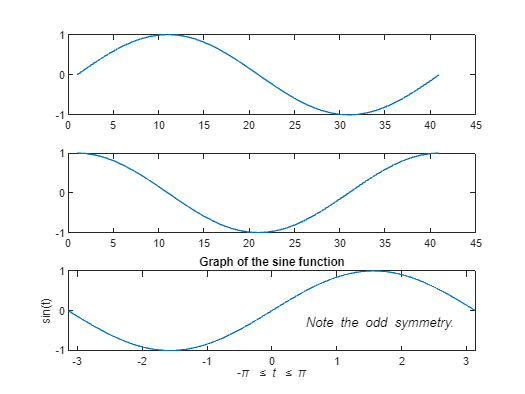

t = -pi:pi/100:pi;
y = sin(t);
plot(t,y)
axis([-pi pi -1 1])
xlabel('-\pi \leq {\itt} \leq \pi')
ylabel('sin(t)')
title('Graph of the sine function')
text(0.5,-1/3,'{\itNote the odd symmetry.}')

     `*Guardar Figuras`

Guarde una figura seleccionando Guardar en el menú Archivo. Esto escribe la figura en un archivo, incluida la propiedad data, its menus, uicontrols, and all annotations.

Para guardar una figura usando un formato de gráficos estándar para usar con otras aplicaciones, como TIFF oJPG, seleccione Guardar como (o Exportar configuración, si desea control adicional) en el menú Archivo.

También puedes guardar desde la línea de comando:

• Utilice la función `savefig` para guardar una figura y los objetos gráficos que contiene como un archivo .fig.

• Utilice el comando `saveas`, incluidas las opciones para guardar la figura en una variedad de formatos.

     `*Cargando una Figura`

Puede cargar figuras en MATLAB utilizando estas funciones:

• Utilice la función `openfig` para cargar figuras guardadas como archivos .fig.

• Utilice la función `imread` para leer archivos de gráficos estándar (incluidas las figuras guardadas) en MATLAB

     `*Guardar datos del espacio de trabajo:`

Puede guardar las variables en su espacio de trabajo seleccionando Guardar espacio de trabajo como en la figura Archivomenú. Puede recargar los datos guardados utilizando el elemento Importar datos en el menú Archivo de la figura. MATLABadmite una variedad de formatos de archivos de datos, incluidos archivos de datos MATLAB, que tienen una extensión .mat.

     `*Crear gráficos de malla y superficie:`

**ACERCA DE LOS GRÁFICOS DE MALLA Y SUPERFICIE**

MATLAB define una superficie mediante las coordenadas z de puntos sobre una cuadrícula en el plano x-y, utilizando líneas rectas.Líneas para conectar puntos adyacentes. Las funciones `mesh` y `surf` muestran superficies en tres dimensiones.

• mesh produce superficies de estructura alámbrica que colorean sólo las líneas que conectan los puntos de definición.

• surf muestra en color tanto las líneas de conexión como las caras de la superficie.

     `*Visualización de funciones de dos variables:`

Para mostrar una función de dos variables, z = f (x,y),

1 Genere matrices X e Y que constan de filas y columnas repetidas, respectivamente, a lo largo deldominio de la función.

2 Usa X e Y para evaluar y representar gráficamente la función.

La función meshgrid transforma el dominio especificado por un solo vector o dos vectores xeyen matrices X e Y para usar en la evaluación de funciones de dos variables. Las filas de X son copias del vector x y las columnas de Y son copias del vector y.

**GRAFICAR LA FUNCIÓN SINC**

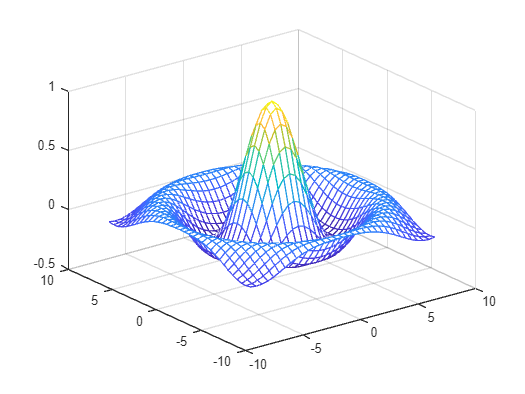

clf; % Limpiar la figura actual

[X,Y] = meshgrid(-8:.5:8); 
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;
mesh(X,Y,Z)

**PARCELAS DE SUPERFICIE COLOREADAS**

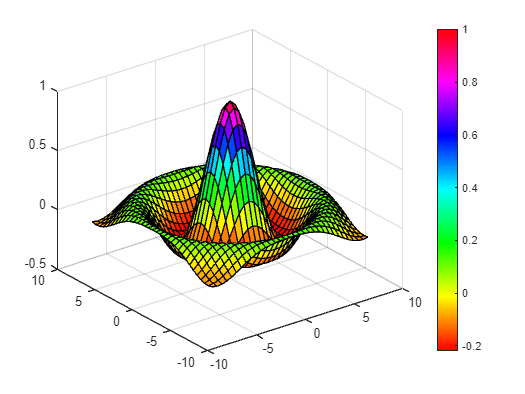

[X,Y] = meshgrid(-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;
surf(X,Y,Z)
%Establece el esquema de colores del gráfico. En este caso, se utiliza el mapa de colores HSV (tono, saturación, valor).
colormap hsv
%Agrega una barra de colores al gráfico
colorbar

**HACER QUE LAS SUPERFICIES SEAN TRANSPARENTES**

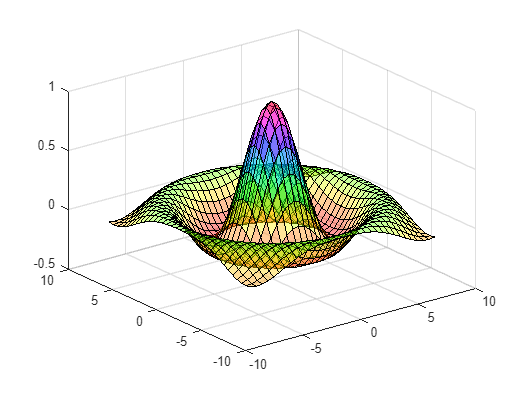

[X,Y] = meshgrid(-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;
surf(X,Y,Z)
colormap hsv
alpha(.4) %establece la transparencia de la superficie creada por la función surf

**ILUMINACIÓN DE PARCELAS SUPERFICIALES CON LUCES**

`[X,Y] = meshgrid(-8:.5:8);`

`R = sqrt(X.^2 + Y.^2) + eps;`

`Z = sin(R)./R;`

`figure; % Crear una nueva figura`

`surf(X,Y,Z,'FaceColor','red','EdgeColor','none')`

`camlight left; %configura la dirección de la luz en la escena tridimensional`

`lighting phong _% establece el modelo de iluminación utilizado para renderizar la superficie`

     `*Mostrar Imágenes:`

**DATOS DE IMÁGEN**

Puede mostrar una matriz numérica 2D como una imagen. En las imágenes, los elementos de la matriz determinan el brillo.o color de las imágenes. Por ejemplo, cargue una matriz de imágenes y su mapa de colores:

`load durer`

`whos`

`Name       Size    Bytes    Class`

`X       648x509 2638656  double array`

`caption 2x28    112      char array`

`map     128x3   3072     double array`

Los elementos de X son números enteros entre 1 y 128, que sirven como índices en el mapa de colores, map. Indique la imagen, use la función imshow:

`imshow(X,map)`

     `*Leer y Escribir imágenes:`

Puede leer archivos de imagen estándar (TIFF, JPEG, PNG, etc.) utilizando la función `imread`. El tipo de cantidad de datos devueltos por imread depende del tipo de imagen que esté leyendo. 

Puede escribir datos de MATLAB en una variedad de formatos de imagen estándar utilizando la función` imwrite.`

     `*Impresión de gráficos:`

**DESCRIPCIÓN GENERAL DE LA IMPRESIÓN**

Puede imprimir una figura de MATLAB directamente en una impresora conectada a su computadora o puede exportarla figura a uno de los formatos de archivos de gráficos estándar que admite MATLAB. Hay dos maneras deimprimir y exportar figuras.

• Utilice las opciones GUI **Print, Print Preview o Export Setup** en el menú Archivo.

• Utilice el comando de impresión para imprimir o exportar la figura desde la línea de comando.

El comando de impresión proporciona un mayor control sobre los controladores y los formatos de archivo. El cuadro de diálogo Vista previa de impresiónEl cuadro le brinda mayor control sobre el tamaño de la figura, las proporciones, la ubicación y los encabezados de página.

**IMPRIMIR DESDE EL MENÚ ARCHIVO**

Hay dos opciones de menú en el menú Archivo que pertenecen a la impresión:

• La opción Print Preview de impresión muestra un cuadro de diálogo que le permite diseñar y diseñar figuras para imprimir.mientras obtiene una vista previa de la página de salida, y desde la cual puede imprimir la figura. Incluye opcionesque anteriormente formaban parte del cuadro de diálogo Configurar página.

• La opción Print muestra un cuadro de diálogo que le permite elegir una impresora, seleccionar impresión estándaropciones e imprimir la figura.

Utilice Vista previa de impresión para determinar si el resultado impreso es el que desea. Haga clic en ImprimirCuadro de diálogo de vista previa Botón Ayuda para mostrar información sobre cómo configurar la página.

**EXPORTAR LA FIGURA A UN ARCHIVO DE GRÁFICOS**

La opción Exportar configuración en el menú Archivo abre una GUI que le permite configurar gráficoscaracterísticas, como el tamaño del texto, la fuente y el estilo, de las figuras que guarda como archivos gráficos. La exportaciónEl cuadro de diálogo de configuración le permite definir y aplicar plantillas para personalizar y estandarizar la salida. Después de la configuración,puede exportar la figura a varios formatos de archivos de gráficos estándar, como EPS, PNG y TIFF.

**USANDO EL COMANDO PRINT**

El comando de impresión proporciona más flexibilidad en el tipo de salida enviada a la impresora y le permitepara controlar la impresión desde archivos de funciones y scripts. El resultado se puede enviar directamente a su predeterminadoimpresora o almacenado en un archivo de salida específico. Está disponible una amplia variedad de formatos de salida, incluidosTIFF, JPEG y PNG.

Por ejemplo, esta declaración guarda el contenido de la ventana de figura actual como un gráfico PNG en elarchivo llamado  `magicsquare.png. `

`print -dpng magicsquare.png `

Para guardar la figura con el mismo tamaño que la figura en la pantalla, utilice estas instrucciones:

`set(gcf,'PaperPositionMode','auto') `

`print -dpng -r0 magicsquare.png` 

Para guardar la misma figura como un archivo TIFF con una resolución de 200 dpi, use el siguiente comando:

`print -dtiff -r200 magicsquare.tiff`

Si escribe imprimir en la línea de comando

`print`

la figura actual se imprime en su impresora predeterminada.

     `*Trabajar con objetos gráficos:`

**OBJETOS GRÁFICOS**

Los objetos gráficos son los elementos básicos utilizados para mostrar gráficos. Estos objetos están organizados en unajerarquía, como se muestra en el siguiente diagrama.Cuando llama a una función de trazado, MATLAB crea el gráfico utilizando varios objetos gráficos, comouna ventana de figura, ejes, líneas, texto, etc. Cada objeto tiene un conjunto fijo de propiedades, que puedesSe utiliza para controlar el comportamiento y la apariencia del gráfico.

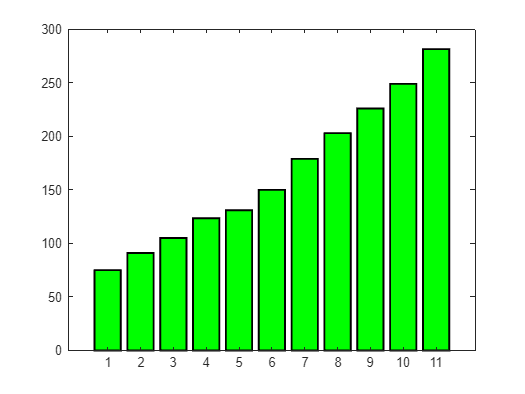

y = [75 91 105 123.5 131 150 179 203 226 249 281.5];
bar(y,'FaceColor','green','EdgeColor','black','LineWidth',1.5)

**OBJETOS GRÁFICOS COMUNES**

Cuando llama a una función para crear un gráfico, MATLAB crea una jerarquía de objetos gráficos. ParaPor ejemplo, llamar a la función de trazado crea los siguientes objetos gráficos:

• Figura: ventana que contiene ejes, barras de herramientas, menús, etc.

• Ejes: sistema de coordenadas que contiene el objeto que representa los datos.

• Línea: líneas que representan el valor de los datos pasados a la función de trazado.

• Texto: etiquetas para marcas de ejes y títulos y anotaciones opcionales.'Diferentes tipos de gráficos utilizan diferentes objetos para representar datos. 

Porque hay muchos, En los gráficos, existen muchos tipos de objetos de datos. Algunos son de uso general, como líneas y rectángulos.y algunos son altamente especializados, como barras de error, barras de colores y leyendas.

**ACCEDER A LAS PROPIEDADES DEL OBJETO**

Las funciones de trazado pueden devolver los objetos utilizados para crear el gráfico. 

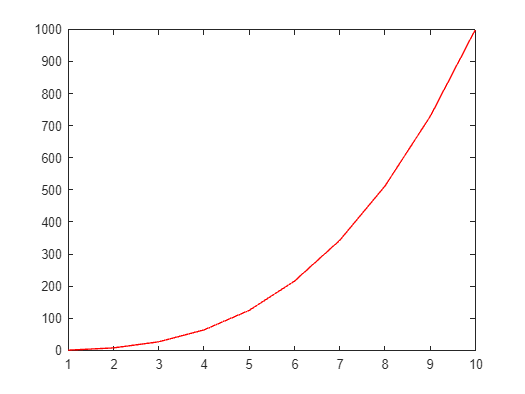

x = 1:10;
y = x.^3;
h = plot(x,y);
h.Color = 'red';

h = plot(x,y,'Color','red');

h.LineWidth %Consultar propiedades de la línea

ans =           0.50


**ENCONTRAR LAS PROPIEDADES DE UN OBJETO**

Para ver las propiedades de un objeto, escriba:

`get(h)`

MATLAB devuelve una lista de las propiedades del objeto con los valores actuales.

Para ver las propiedades de un objeto con información sobre valores posibles, escriba:

`set(h)`

     `*Establecer propiedades de objeto`

**ESTABLECER PROPIEDADES DE OBJETOS EXISTENTES**

Para establecer la misma propiedad con el mismo valor en varios objetos, utilice la función set.

y = magic(5);
h = plot(y);
set(h,'Marker','s','MarkerFaceColor','g')

En este caso, h es un vector que contiene cinco identificadores, uno para cada una de las cinco líneas del gráfico. 

Para establecer un valor de propiedad en un objeto, indexe en la matriz de identificadores:

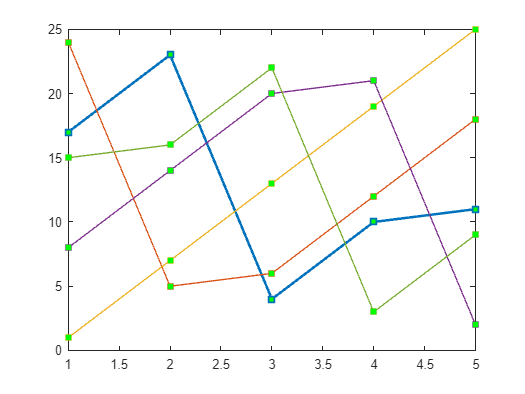

h(1).LineWidth = 2;

**ESTABLECER MÚLTIPLES VALORES DE PROPIEDAD**

Si desea establecer las propiedades de cada línea en un valor diferente, puede usar matrices de celdas para almacenar todaslos datos y pasarlos al comando set. 

figure
y = magic(5);
h = plot(y);

Supongamos que desea agregar diferentes marcadores a cada línea y colorear la cara del marcador del mismo color como la línea. Debe definir dos matrices de celdas: una que contenga los nombres de las propiedades y la otra que contiene los valores deseados de las propiedades.

prop_name(1) = {'Marker'};
prop_name(2) = {'MarkerFaceColor'};

La matriz de celdas prop_values contiene 10 valores: cinco valores para la propiedad Marcador y cinco valores para la propiedad MarkerFaceColor. Observe que prop_values es una matriz de celdas bidimensional. ElLa primera dimensión indica a qué identificador en h se aplican los valores y la segunda dimensión indicaa qué propiedad se asigna el valor:

prop_values(1,1) = {'s'};
prop_values(1,2) = {h(1).Color};
prop_values(2,1) = {'d'};
prop_values(2,2) = {h(2).Color};
prop_values(3,1) = {'o'};
prop_values(3,2) = {h(3).Color};
prop_values(4,1) = {'p'};
prop_values(4,2) = {h(4).Color};
prop_values(5,1) = {'h'};
prop_values(5,2) = {h(5).Color};

Al MarkerFaceColor siempre se le asigna el valor del color de la línea correspondiente (obtenido por la propiedad Color de línea).Después de definir las matrices de celdas, llame a set para especificar los nuevos valores de propiedad:

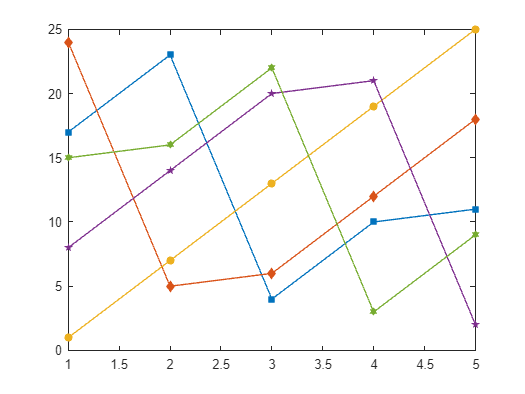

set(h,prop_name,prop_values)

     `*Funciones para trabajar con objetos:`

Funciones comunmente utilizadas cuando se trabaja con objetos:

   ** allchild**: Encuentra todos los hijos de objetos especificados.

     **ancestor**: Encuentra el ancestro del objeto gráfico.

    **copyobj: **Copiar objeto gráfico.

**    delete: **Eliminar un objeto.

**    findall: **Encuentra todos los objetos gráficos (incluidos los identificadores ocultos).

**    findobj: ** Encuentra los identificadores de objetos que tienen valores de propiedad específicos.

**    gca: **Devuelve el identificador de los ejes actuales.

**    gcf: **Devuelve el identificador de la figura actual.

**    gco: **Devuelve el identificador del objeto actual.

**    get: **Consulta los valores de las propiedades de un objeto.

**    ishandle: **Verdadero si el valor es un identificador de objeto válido.

**    set: **Establece los valores de las propiedades de un objeto.

     `*Pasar Argumentos:`

Puede definir funciones de trazado especializadas para simplificar la creación de gráficos personalizados. Al definir una función, puede pasar argumentos como funciones de trazado de MATLAB.

El siguiente ejemplo muestra una función de MATLAB que evalúa una expresión matemática sobre elrango especificado en el argumento de entrada x, y luego traza los resultados. Una segunda llamada a la función de trazado.traza el valor medio de los resultados como una línea roja.La función modifica los ticks del eje y según los valores calculados. Las etiquetas de los ejes y un título completan elgráfico personalizado.

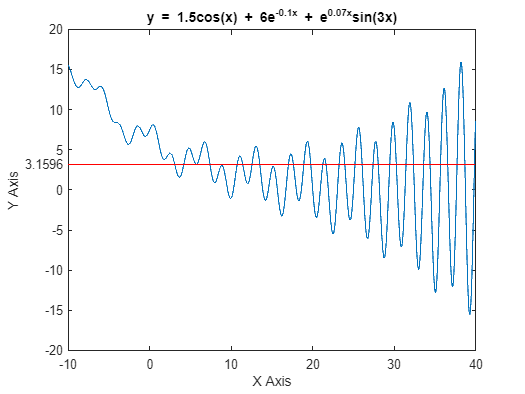

x = -10:0.005:40;
plotFunc(x);

%La función plotFunc(x) se encuentra al final del script

     `*Encontrar los identificadores de objetos existentes:`

La función findobj le permite obtener los identificadores de objetos gráficos buscando objetoscon valores de propiedad particulares. Con findobj puedes especificar los valores de cualquier combinación depropiedades, lo que facilita elegir un objeto entre muchos. findobj también reconoce expresiones regulares.

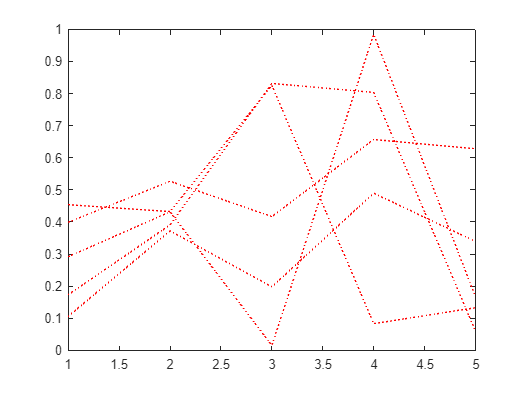

%Encontrar todos los objetos de un determinado tipo
h = findobj('Type','patch');
%Encontrar los objetos con una propiedad particular
plot(rand(5),'r:')

h = findobj('Type','line','Color','r','LineStyle',':');
%Limitar el alcance de la búsqueda
h = findobj(gca, 'Type', 'text', 'String', '\\pi/2');

function plotFunc(x)
 y = 1.5*cos(x) + 6*exp(-.1*x) + exp(.07*x).*sin(3*x);
 ym = mean(y);
 hfig = figure('Name','Function and Mean');
 hax = axes('Parent',hfig);
 plot(hax,x,y)
 hold on
 plot(hax,[min(x) max(x)],[ym ym],'Color','red')
 hold off
 ylab = hax.YTick;
 new_ylab = sort([ylab, ym]);
 hax.YTick = new_ylab;
 title ('y = 1.5cos(x) + 6e^{-0.1x} + e^{0.07x}sin(3x)')
 xlabel('X Axis')
 ylabel('Y Axis')
end